clc
clear all
close all

pt1 = pcread("pointcloudnewbag.pcd");
pt2 = pcread("pointcloudnew3.pcd");
pt3 = pcread("pointcloudnew6.pcd");

rotX = [1 0 0;
        0 -1 0;
        0 0 -1];

rotY = [-1 0 0;
        0 1 0;
        0 0 -1];

rotZ = [-1 0 0;
        0 -1 0;
        0 0 1];

rot = rotX * rotZ;

tform = rigid3d(rot, [0,0,0]);

pt1 = pctransform(pt1,tform);
pt2 = pctransform(pt2,tform);
pt3 = pctransform(pt3,tform);

a = figure;

a =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


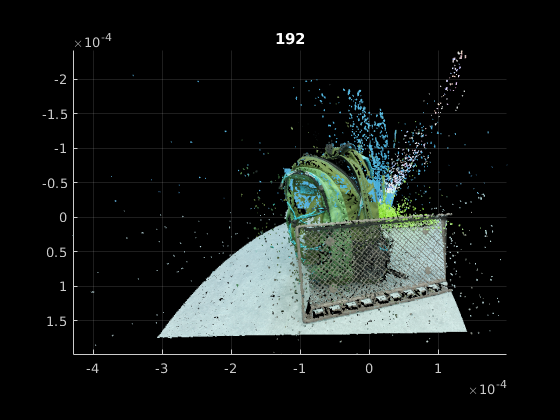

% subplot(2,2,1)
pcshow(pt1)
title("192")
view([0 0 -1])
saveas(a,'192.png')


b = figure;

b =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


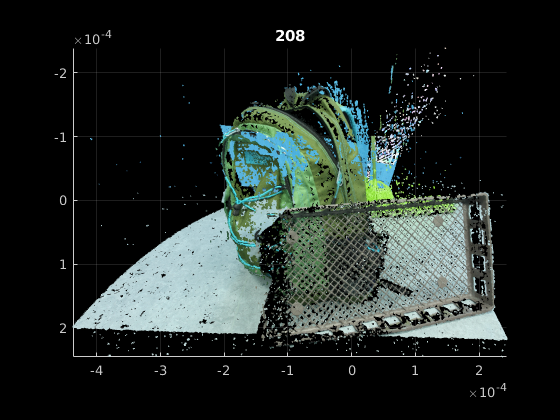

% subplot(2,2,2)
pcshow(pt2)
title("208")
view([0 0 -1])
saveas(b,'208.png')


c = figure;

c =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


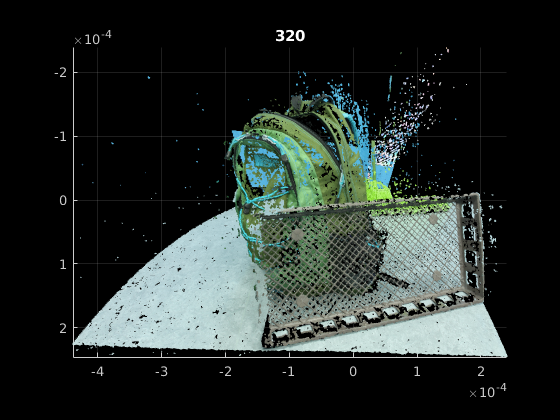

% subplot(2,2,3)
pcshow(pt3)
title("320")
view([0 0 -1])
saveas(c,'320.png')

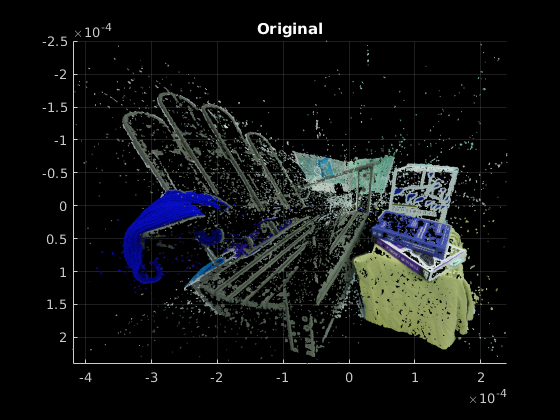

pt1 = pcread("pointcloudnew2.pcd");
pt2 = pcread("pointcloudnew3_Gblur.pcd");
pt3 = pcread("pointcloudnew3_LOG.pcd");
pt4 = pcread("pointcloudnew3_more_Gblur.pcd");

rotX = [1 0 0;
        0 -1 0;
        0 0 -1];

rotY = [-1 0 0;
        0 1 0;
        0 0 -1];

rotZ = [-1 0 0;
        0 -1 0;
        0 0 1];

rot = rotX * rotZ;

tform = rigid3d(rot, [0,0,0]);

pt1 = pctransform(pt1,tform);
pt2 = pctransform(pt2,tform);
pt3 = pctransform(pt3,tform);
pt4 = pctransform(pt4,tform);

a = figure;
% subplot(2,2,1)
pcshow(pt1)
title("Original")
view([0 0 -1])
saveas(a,'orignal.png')

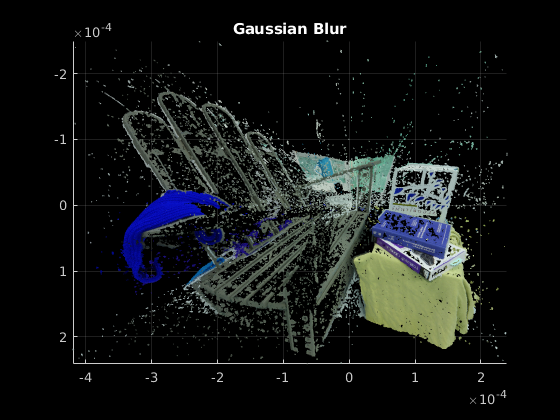


b = figure;
% subplot(2,2,2)
pcshow(pt2)
title("Gaussian Blur")
view([0 0 -1])
saveas(b,'gBlur.png')

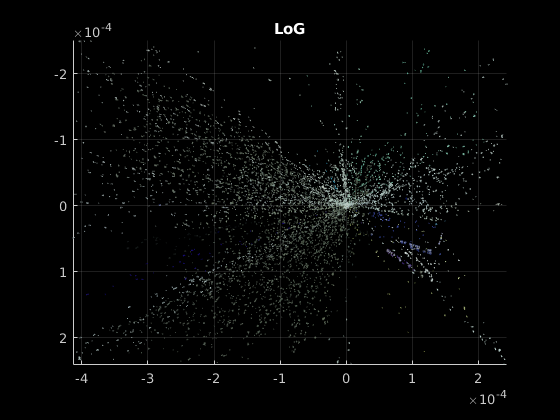


c = figure;
% subplot(2,2,3)
pcshow(pt3)
title("LoG")
view([0 0 -1])
saveas(c,'LoG.png')

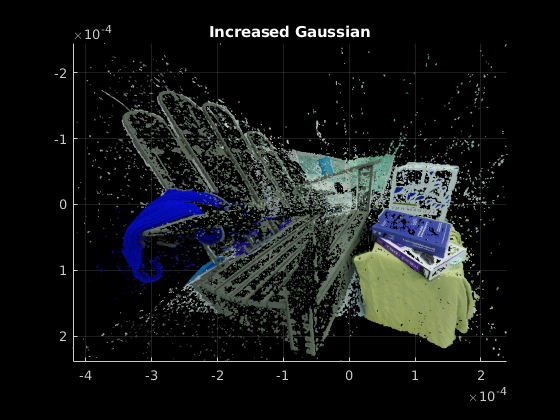


d = figure;
% subplot(2,2,3)
pcshow(pt4)
title("Increased Gaussian")
view([0 0 -1])
saveas(d,'ggBlur.png')